# 利用PSYCHTOOLBOX生成视觉刺激

## 要点

- 使用Screen函数 

- 窗口化与制作mask的程序 

  **问题27**: 马赫带的意义和代码编写？

  **问题28**:Alphablending是什么，有哪些用途？

  **问题29**:列举常用光栅的代码实现？

  **问题30**:棋盘格生成的方法？

  **问题31**:怎样画红黑棋盘格？

**问题32**: 盲人摸象、管中窥豹、鱼眼技术等如何用二维高斯窗口实现？

**问题33**:窗口化函数的应用，包括fMRI实验的V1定位？ 


%  问题27: 马赫带的意义和代码编写？

clear all %清除变量，MEX等，如果有需要的变量还不想清除，不能用这个语句
close all % 关闭各种figure窗口
img=1:10; %图片的值，即是选择colormap第1-10的值
figure(1) %打开figure编号为1的窗口
paintpots = ones(10,3); % 自己创建的一个颜色查找表
colormap(paintpots) %将定义好的对应关系输入系统
image(img);%呈现图片
axis off; %取消在这个任务中没有意义的坐标轴
for i=1:10
    paintpots (i,:)= (i/10);%令查找表的第i位的值为i/10，即是最大亮度的i/10
    colormap(paintpots);%将更新的查找表输入系统
    pause %等待按键，注意看figure中图片的变化
end

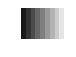

% 初始化Psychtoolbox和屏幕
PsychDefaultSetup(2); % 默认设置
screenNumber = max(Screen('Screens')); % 选择最大的屏幕编号

Screen('Preference', 'SkipSyncTests', 1);           

% 打开窗口
[window, windowRect] = Screen('OpenWindow', screenNumber, 0);
[screenXpixels, screenYpixels] = Screen('WindowSize', window); % 获取屏幕尺寸
Screen('BlendFunction', window, 'GL_SRC_ALPHA', 'GL_ONE_MINUS_SRC_ALPHA');

% 计算宽条位置
rectWidth = screenXpixels/10; % 定义条的宽度
baseRect = [0 0 rectWidth screenYpixels]; % 定义矩形大小

          
for i = 1:10
    rectColor = repmat((255*(i/10)), 1, 3); % 设置当前亮度颜色
    centeredRect = CenterRectOnPointd(baseRect, (i-1)*rectWidth+rectWidth/2, screenYpixels / 2);
    
    % 画出当前亮度的宽条
    Screen('FillRect', window, rectColor, centeredRect);
    Screen('Flip', window, [], 1); % 显示当前帧
    WaitSecs(1)



PTB-INFO: This is Psychtoolbox-3 for Microsoft Windows, under Matlab 64-Bit (Version 3.0.19 - Build date: Dec 14 2023).
PTB-INFO: OS support status: Windows 11 (Version 11.0) is not supported.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid support, support memberships and other commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.

PTB-INFO: The detected endline of the vertical blank interval is equal or lower than the startline. This indicates
PTB-INFO: that i couldn't detect the duration of the vertical blank interval and won't be able to correct timestamps
PTB-INFO: for it. This will introduce a very small and constant offset (typically << 1 msec). Read 'help Beamposit

   % KbStrokeWait; % 等待按键继续
end

% 结束程序
 Screen('Flip', window); % 显示当前帧
 WaitSecs(2);
sca; % 关闭所有屏幕 

** 呈现透明刺激**

透明度：

调整透明度的通道叫做alpha通道,即[R G B A]中第四个通道A。

例如：image2(:,:,4) = alpha;

alpha 取值范围为0~255,0为完全不透明,255为完全透明。

在书写Screen函数时,需要设置BlendFunction,并加上程序开头:

Screen('BlendFunction', w , GL_SRC_ALPHA,GL_ONE_MINUS_SRC_ALPHA);

### 关于alpha blending的原理：

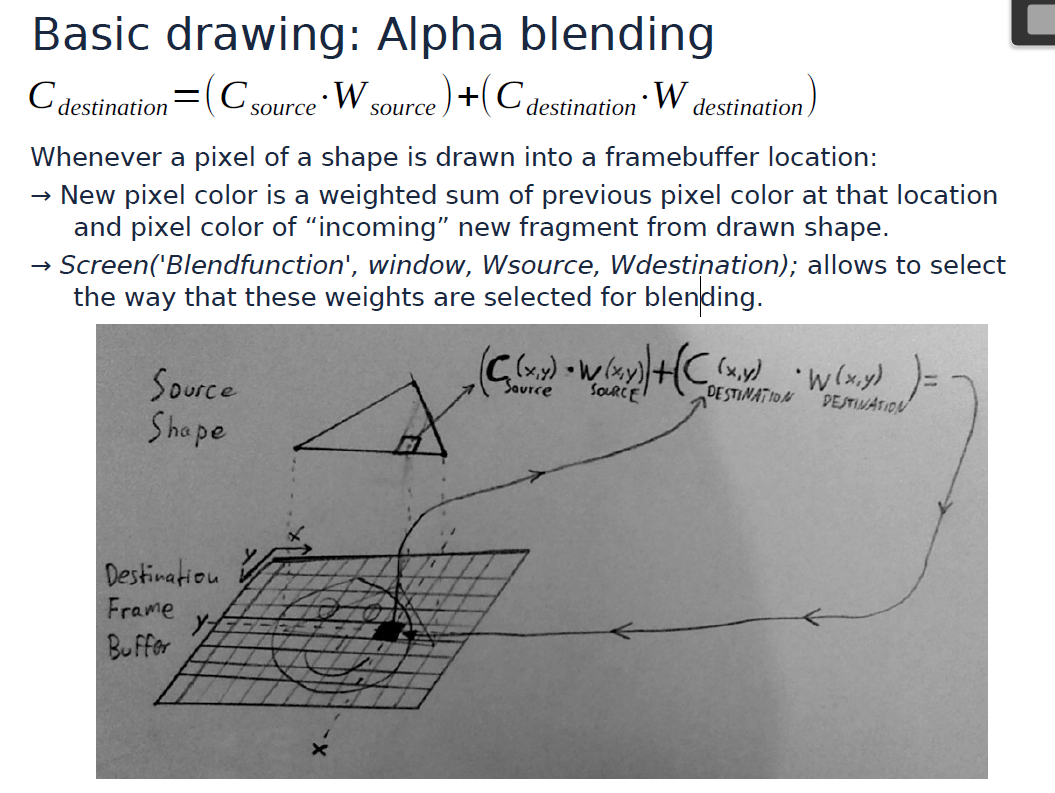

% 问题28:Alphablending是什么，有哪些用途？
 
% 参考Programofalphablend.m 

ans = 3.2366e+05

ans = 3.2366e+05

ans = 3.2366e+05

ans = 3.2367e+05

ans = 3.2367e+05

ans = 3.2367e+05

ans = 3.2367e+05

ans = 3.2367e+05

ans = 3.2367e+05

ans = 3.2367e+05

try
    whichscreen = max(Screen('Screens')); % count the screens
    [w, rect] = Screen('OpenWindow', whichscreen, 0); % open it

    midsquare = CenterRect([0, 0, 100, 100], rect);
    squares = [AdjoinRect(midsquare, midsquare, RectLeft); ...
        midsquare; ...
        AdjoinRect(midsquare, midsquare, RectRight)];
    colors = [255/2, 255/2, 255/2; ...
        0, 0, 0; ...
        255/2, 255/2, 255/2];
    Screen('FrameRect', w, colors', squares', 5);
    Screen('Flip', w);
    KbWait;
    Screen('CloseAll');
catch
    screen('CloseAll')
    rethrow(lasterror)
end 

#### 【练习】 用批处理的方式，PTB画5根线段

**  问题29**:列举常用光栅的代码实现？

  **问题30**:棋盘格生成的方法？

  **问题31**:怎样画红黑棋盘格？

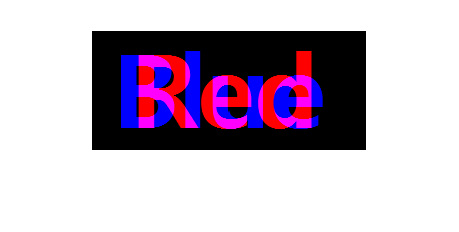

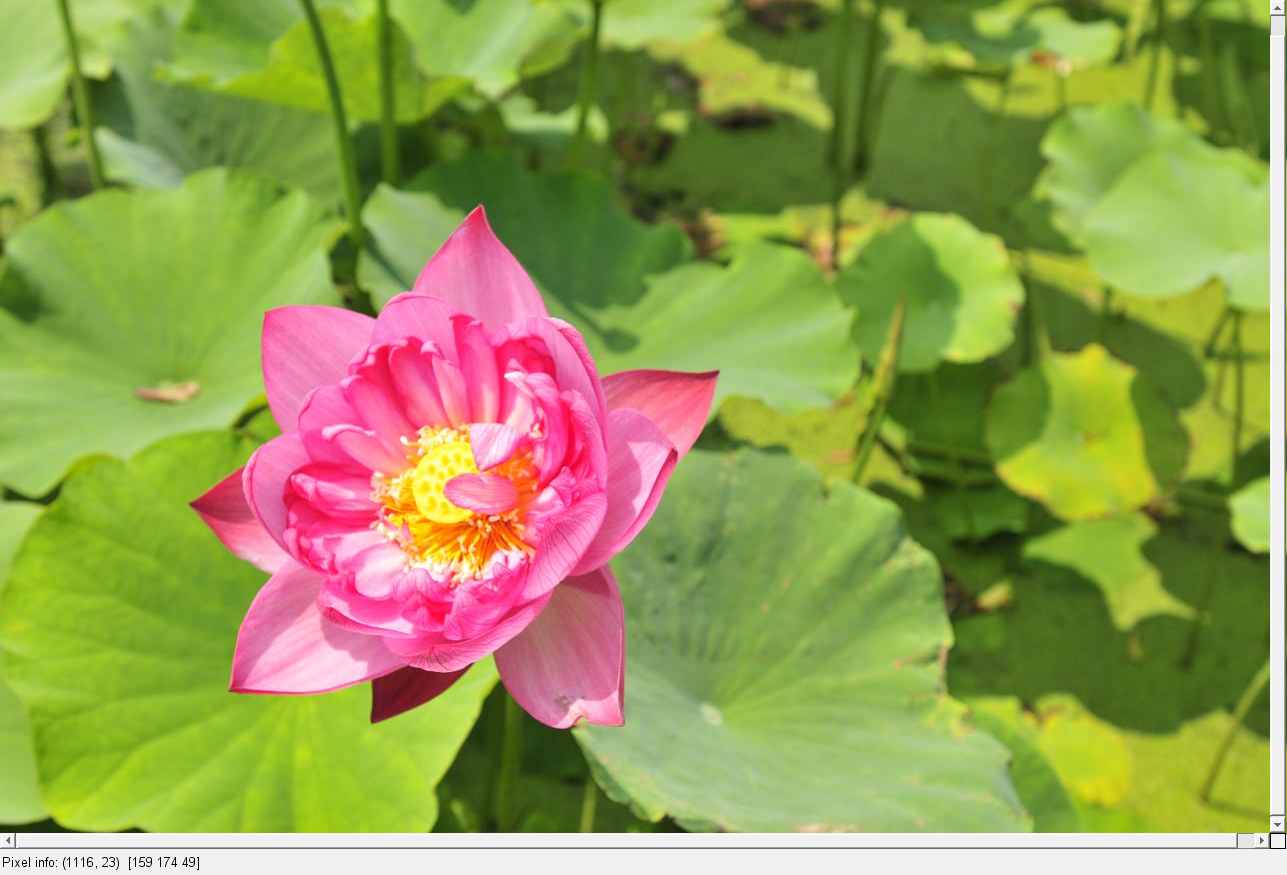

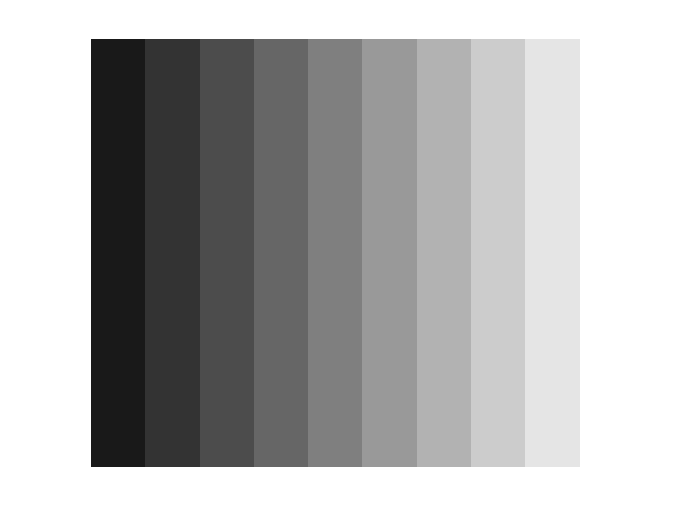



PTB-INFO: This is Psychtoolbox-3 for Microsoft Windows, under Matlab 64-Bit (Version 3.0.14 - Build date: Dec 12 2016).
PTB-INFO: Support status on this operating system release: Windows version 10.0 supported and tested to some limited degree.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.



PTB-INFO: OpenGL-Renderer is Intel :: Intel(R) HD Graphics 530 :: 4.5.0 - Build 22.20.16.4836
PTB-INFO: VBL startline = 1080 , VBL Endline = -1
PTB-INFO: Beamposition queries unsupported or defective on this system. Using basic timestamping as fallback: Timestamps returned by Screen('Flip') will be less robust and accurate.
PTB-INFO: Measured monitor refresh interval from VBLsync = 0.000000 ms [1.#INF00 Hz]. (0 valid samples taken, stddev=

% 网格矩阵
[x,y] = meshgrid(1:3,1:3);

正弦光栅：

close all;
[x,y]=meshgrid(1:400,1:400);%制作坐标网格
gra=(sin(x/10)+1)/2;%画光栅,除以10是为了增大周期,加1后除以2是把值域从[-1,1]转到[0,1],值域问题在画图中经常容易被忽略,如果数据的值域不合适,会出现各种奇怪的问题
imshow(gra);%呈现图片

棋盘格图案：

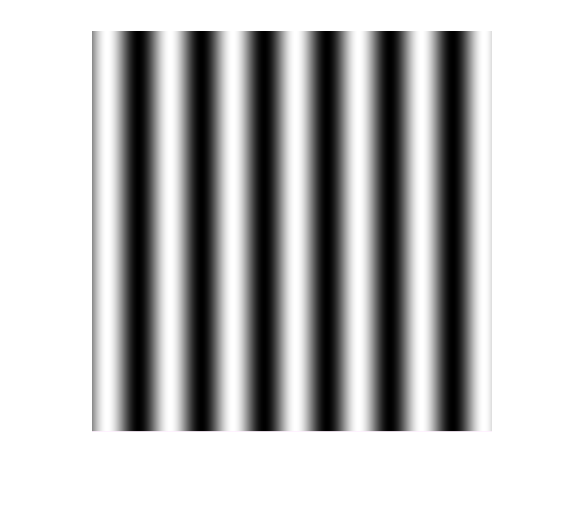

%画棋盘格
a=[ones(400,40),zeros(400,40)]; %先生成一根白条和一根黑条
a1=repmat(a,[1,5]); % 将这个组合复制5遍
a2=xor(a1,a1');%将这个黑白条纹与自己的转置做异或逻辑运算
imshow(a2) %棋盘格就生成了

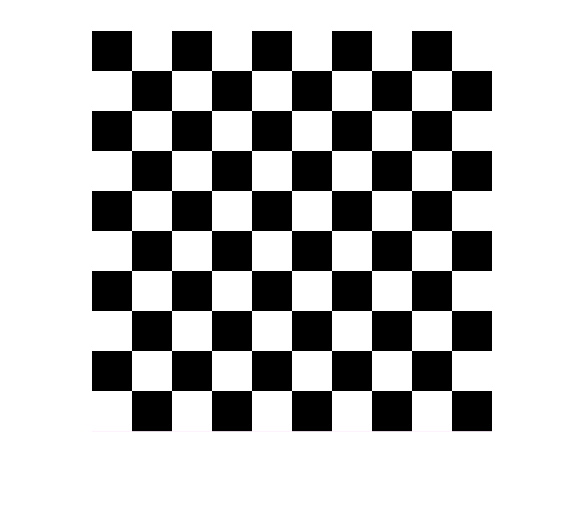

% Create a grid of x and y coordinates
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);


% Define the function to plot
Z = sin(sqrt(X.^2 + Y.^2));

% Create the 3D plot
figure;
surf(X, Y, Z);

% Add labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Surface Plot');

% Customize the plot
shading interp; % interpolate shading for smoother appearance
colormap('jet'); % set the colormap to jet

% Show the plot

更常用的方法还是通过正弦周期函数来构造周期图形：

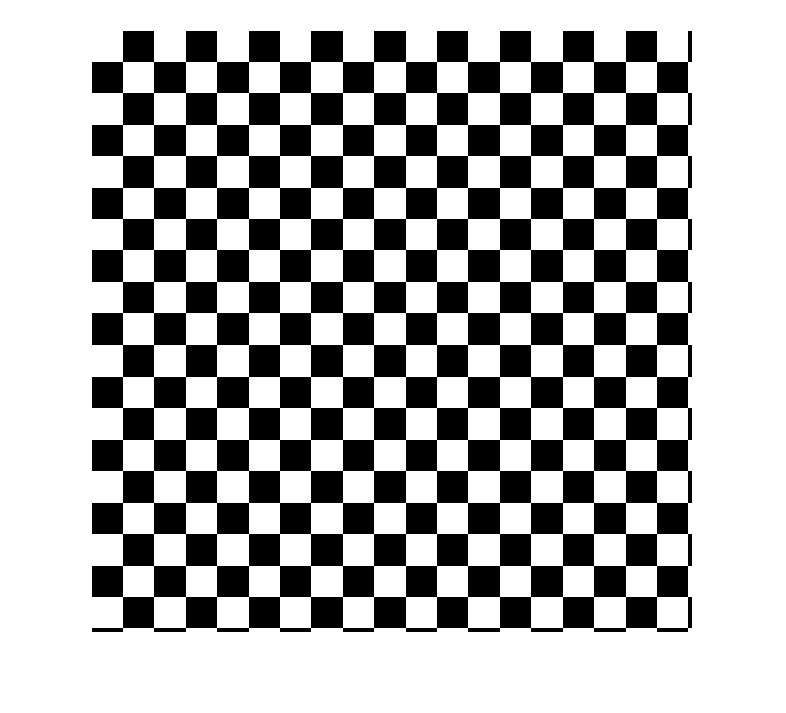

%画棋盘格方法二

clear all
close all
[x,y]=meshgrid(1:600,1:600); %制作坐标网格
x1=sin(x/10);%值域为[-1,1];
y1=sin(y/10);
c=x1.*y1;%负负得正
pic=c>0; % 最后逻辑判断，得到棋盘格
imshow(pic)

 窗口化

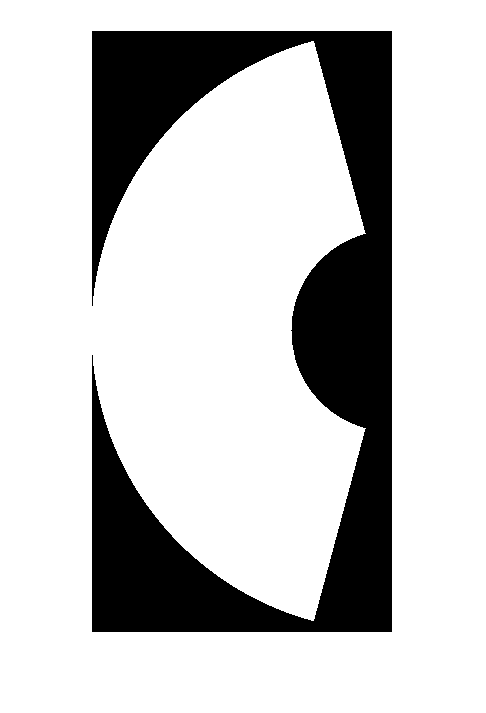

% 制作扇形mask

[x,y]=meshgrid(1:300,1:600);% 制作网格
Fan_dis=sqrt((x-300).^2+(y-300).^2);%计算所有点到[300 300]这个坐标点的距离
Fan_an=(y-300)./(x-300);%计算所有点到[300 300]这个坐标点的连线的正切值
mask=Fan_dis>100&Fan_dis<300&Fan_an>-tand(75)&Fan_an<tand(75);%做逻辑判断，即可得到我们需要的特定图形的mask
figure
imshow(mask)

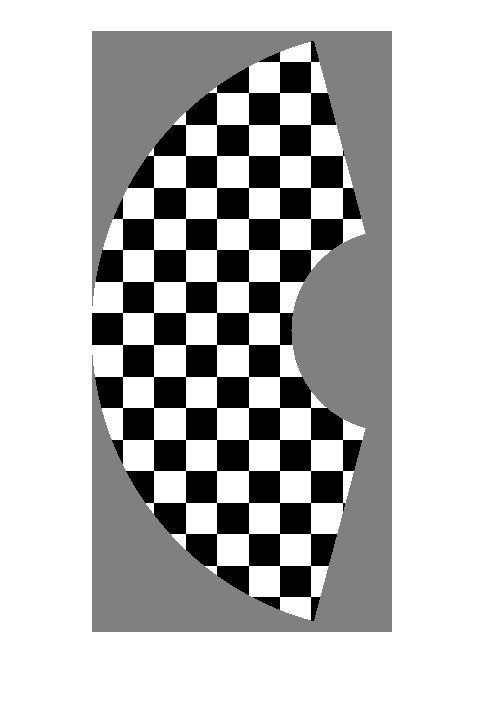

%窗口化的棋盘格

pic=double(pic);%将逻辑型的pic转成double型
loca=pic==0; % pic接上一题的棋盘格，找到所有黑色点的坐标；
pic(loca)=1/255; %将0置换成一个接近0的很小的值
pic1=pic(:,1:300).*mask; %mask就是扇子的01二值图
pic1(pic1==0)=0.5; % 将点乘完周围黑色的地方找到，然后变成灰色。
pic1(pic1==1/255)=0; %可以再把刚才的极小值再找到，重新赋值0
figure
imshow(pic1)

利用二维高斯概率密度函数来制作高斯窗口：

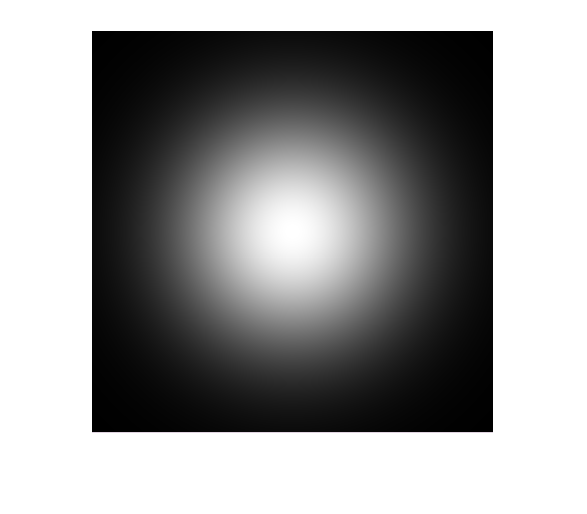


clear all
close all
[x,y]=meshgrid(1:401,1:401); %做好画布永远是第一步
sigma=80; %我们假设高斯的sigma是80个像素。
x0=201; %假设高斯的中心为横坐标第201个像素
y0=201; %纵坐标也为第201个像素
pic=exp(-1/(sigma^2*2)*((x-x0).^2+(y-y0).^2)); %exp前面的常数可以不写，这时峰值是最大值1
imshow(pic)

制作600*600的图像，底色为灰色，mask后露出的窗口为以中心为圆心，内外半径分别为100、200的圆环，mask下的内容为红黑棋盘格，参考图像如下（灰度任意，棋盘格子的大小不作要求，可看出是棋盘即可）

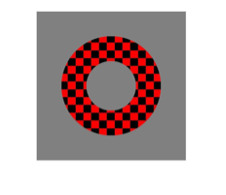

%建立棋盘
[X,y]=meshgrid(1:600,1:600);
x1=sin(X/10);
y1=sin(y/10);
c1=x1.*y1;
pic(:,:,1)=c1>0;
pic(:,:,3)=zeros(600);

%建立mask 覆盖棋盘
dis=sqrt((X-300).^2+(y-300).^2);
mask=dis>100 & dis<200; 
%覆盖
pic=double(pic);
lol=pic==0;%找到黑色的位置
pic(lol)=1/255;%黑色转为其他色，用来区分mask的数值
pic1=pic.*mask;
pic1(pic1==0)=0.5;%mask位置灰色
pic1(pic1==1/255)=0;%黑色变回来
figure;
image(pic1);
axis off;

bg_color = 128;
bg_image = ones(600, 600) * bg_color;
board_size = 50;
board_image = zeros(600, 600, 3);
for i = 1:board_size:600
    for j = 1:board_size:600
        if mod((i-1)/board_size + (j-1)/board_size, 2) == 0
            board_image(i:min(i+board_size-1, 600), j:min(j+board_size-1, 600), 1) = 255;
        end
    end
end
[X, Y] = meshgrid(1:600, 1:600);
center = 300.5;
mask = ((X - center).^2 + (Y - center).^2 >= 100^2) & ((X - center).^2 + (Y - center).^2 <= 200^2);
masked_board = double(repmat(mask, [1, 1, 3]));
final_image = masked_board .* board_image + (1 - masked_board) .* repmat(bg_image, [1, 1, 3]);
imshow(uint8(final_image));

**问题32**: 盲人摸象、管中窥豹、鱼眼技术等如何用二维高斯窗口实现？ 

 dynamicgaussianmask.m 通过这个程序，了解二维高斯窗口的应用，以及GetMouse函数的用法  

clear all
close all
pic1=imread('flower.jpg');% 先将准备好的图片读取
[x,y,z]=size(pic1);  %提取三维的大小
[X,Y] = meshgrid(1:y, 1:x); %按照这个大小制作网格
sigma=50; %设置高斯的sigma
while 1 %这个代表死循环
[x0,y0,button] = GetMouse; %新函数出现，鼠标派上用场，x0是鼠标横坐标，y0是鼠标纵坐标，button是鼠标的按键情况。
if button(3)~=0 %如果按了右键
close all % 关掉动画
break %并且跳出，唯一的出口
end
ga = exp((-1/2/sigma^2)*((X-x0).^2+(Y-y0).^2));%在网格上画个高斯
ga=repmat(ga,[1,1,3]); %由于图片是三维的，多了RGB通道，高斯也复制自己变三维
tmp = double(pic1).* ga; %画出窗口化的图片，double了才能用四则运算。
imshow(tmp/255) %由于tmp现在值域是[0,255]，且是double，除以255也是为了归一化
pause (0.04) %为了不让图片刷新太快，0.04秒是为了模拟25Hz
end

**问题33**:窗口化函数的应用，包括fMRI实验的V1定位？

    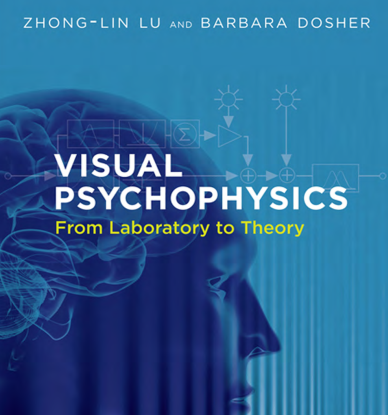

Li, X., Lu, Z. L., Tjan, B. S., Dosher, B. A., & Chu, W. (2008).  Blood oxygenation level-dependent contrast response functions identify  mechanisms of covert attention in early visual areas. *Proceedings of the National Academy of Sciences of the United States of America*, *105*(16), 6202–6207. https://doi.org/10.1073/pnas.0801390105 

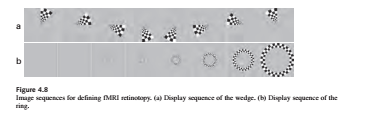

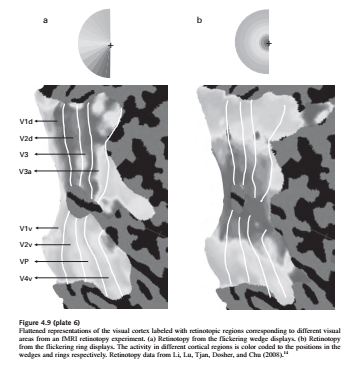

% Copyright (c) 2013, Massachusetts Institute of Technology
% This program was presented in the book "Visual Psychophysics:
% From Laboratory to Theory" by Zhong-Lin Lu and Barbara Dosher.
% The book is available at http://mitpress.mit.edu/books/visual-psychophysics

%%% Program WedgeRing.m
[x,  y] = meshgrid(-1024:1023,  1024:-1:-1023);
theta = atan2(y,  x);  % translates x, y to polar angle
r = sqrt(x.^2 + y.^2); % and radius
sWidth = pi/8;         % width of each wedge in polar angle
mask1 = 2*round((sin(theta*2*(2*pi/sWidth)) + 1)/2) - 1; 
                       % make wedge pattern
r0=[ 64 96 144 208 288 400 528 672 832 1024]; 
                       % radii of different rings
mask2 = (r < r0(1));
for i = 2:10
  mask2 = mask2 + (2*mod(i,2) - 1)*(r >= r0(i-1) & r < r0(i));
end
mask3 = mask1.*mask2;
Wmask = (theta  > -pi/6 & theta < pi/6);
Rmask = (r > 64 & r <= 144) + (r > 672 & r < 1024);
Wedge = Wmask.*mask3*127 + 128;
Ring = Rmask.*mask3*127 + 128;
showImage(Wedge,   'grayscale');
showImage(Ring,   'grayscale');

% Wedge
% Ring